# Importing and analyzing weather data from ThingSpeak

[ThingSpeak](https://www.mathworks.com/products/thingspeak.html) is an IoT analytics service that allows you to aggregate, visualize, and analyze live data streams in the cloud. ThingSpeak provides instant visualizations of data posted by your devices to ThingSpeak. With the ability to execute MATLAB code in ThingSpeak, you can perform online analysis and process data as it comes in. ThingSpeak is often used for prototyping and proof-of-concept IoT systems that require analytics. 

## Weather Station Data

ThingSpeak-hosted data can also seamlessly be imported into MATLAB for more advanced analytics or to be integrated into other workflows.

We will import data collected from a weather station located at the MathWorks' headquarters in Natick Massachusetts (West Garage, Natick, MA 01760, USA) 

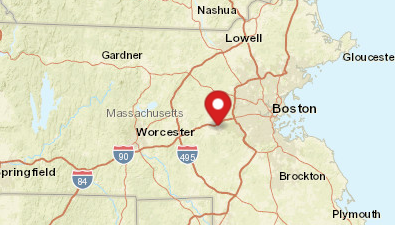

The information is collected, aggregated and analyzed with [Public ThingSpeak channel 12397](https://thingspeak.mathworks.com/channels/12397)

More information about the weather station can be found [here](https://www.hackster.io/mawrey/solar-powered-cellular-weather-station-e5a3ed).

## Import Data from ThingSpeak Channel

The function [thingSpeakRead](https://www.mathworks.com/help/thingspeak/thingspeakread.html) allows you to read data stored in a ThingSpeak channel

To retrieve the most recent data from the channel, we only need to specify the channel ID as the function input argument.

Data is saved as an array with the value of the fields in the channel.

channelID = 12397;
data = thingSpeakRead(channelID)

## Importing specific fields into a table

Standard ThingSpeak channels have up to 8 data fields. The thingSpeakRead allows you to specify the fields to retrieve.

Also, the data can be read as array (matrix), [table](https://www.mathworks.com/help/matlab/tables.html), or [timetable](https://www.mathworks.com/help/matlab/ref/timetable.html?s_tid=doc_ta). 

Given that our %Humidity, Temperature, Rain, and Pressure data are time series, we will import those fields into a timetable.

data2 = thingSpeakRead(channelID,'Fields',[3,4,5,6],OutputFormat='TimeTable')

## Import one week worth of data

Multiple data points can be read using different arguments - number of points, number of minutes, specific timestamps, dates.

In this case we will read all data from the past week.

dataLastWeek = thingSpeakRead(channelID,Fields=[3,4,5,6],...
    DateRange=[datetime('today')-7,datetime('today')],OutputFormat="timetable")

## Visualizing Temperature

We will use a [Live Editor Task ](https://www.mathworks.com/help/matlab/matlab_prog/add-live-editor-tasks-to-a-live-script.html)to interactively visualize our temperature data.

## Smoothing Data

To understand how temperature varied throughout the week while ignoring minor daily temperature changes, we will smooth the data using another Live Editor Task.

% Smooth input data
[dataSmooth,winSize] = smoothdata(dataLastWeek,"gaussian",SmoothingFactor=0.3, ...
    DataVariables="TemperatureF");

% Display results
figure
plot(dataLastWeek.Timestamps,dataLastWeek.TemperatureF,SeriesIndex=6, ...
    DisplayName="Input data")
hold on
plot(dataLastWeek.Timestamps,dataSmooth.TemperatureF,SeriesIndex=1, ...
    LineWidth=1.5,DisplayName="Smoothed data")
hold off
title("Moving window size: " + string(winSize));
legend
ylabel("TemperatureF")
xlabel("Timestamps")
clear winSize